# Electric Charges and Electric Fields 

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

Electric charges and fields are at the heart of electromagnetism,  explaining everything from static cling to lightning. In this lesson,  we'll use MATLAB to visualize and compute electric fields, making these  invisible forces more tangible and easier to understand. 

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Electric Charge and Coulomb Force 

Electric charge is a property of matter that causes it to experience a force when placed in an electromagnetic field. Charges are either positive or negative, and like charges repel while opposite charges attract.

Given two local charge A and B in space -> F A->B and F B->A

The force between a point charge $A$ (with charge $q_A$) and a point charge $B$ (with charge $q_B$) is described by Coulomb's law, which can be expressed in different forms:


$$ \vec{F_{B\rightarrow A}} = k_e \frac{q_A q_B}{r^3}\vec{r}_{B\rightarrow A} \qquad(1)$$



$$ \vec{F_A} = k_e \frac{q_A q_B}{r^2}{\hat{r}}_{B\rightarrow A} \qquad(2)$$



$$ \vec{F_A}
 = \frac{1}{4\pi\varepsilon_0}\frac{q_A q_B}{r^3}\vec{r}_{B\rightarrow A} \qquad(3)$$



$$ \vec{F_A} = \frac{1}{4\pi\varepsilon_0}\frac{q_A q_B}{r^2}{\hat{r}}_{B\rightarrow A} \qquad(4)$$


Note that the four expressions above are equivalent, with:

- $k_e$ is the Coulomb constant, which can be expressed as a function of the vacuum electric permittivity $\varepsilon_0$: $k_e=\frac{1}{4\pi\varepsilon_0}=8.987\times10^9 \quad (\text{N}\cdot\text{m}^2\cdot\text{C}^{-2})$

- $\vec{r}_{B\rightarrow A}$ is the displacement vector from $B$ to $A$, $r = ||\vec{r}_{B\to A}||$ is its magnitude, and ${\hat{r}} = \frac{\vec{r}_{B\to A}}{r}$ its unit vector

 **Info.** All of Coulomb's law forms expressed above are equivalent; depending on the textbook you are using, you might see one of those or even a slightly different one.

  **Try. **Using the slider and spinner below, visualize the force between a charge particle $A$ $(+1 \text{ mC})$ and a charged particle $B$ of varying charge at different distances:

- You might end up in situation where the force is so small that you can't even see the arrow, in this case try using logarithmic scale or the zoom tool .

- The position of the charges will change depending on the distance.

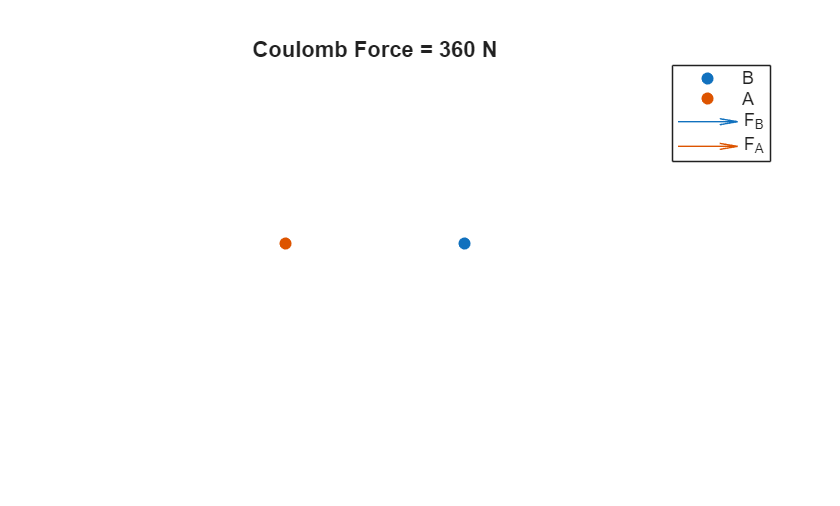


PlotCoulombForce(1,...
    5,...
    false)


function PlotCoulombForce(Charge,rTest,logScale)
% Define parameters for the charges and distance
Charge = Charge*1e-3;
TestCharge = 1e-3;
k_e = 8.99e9; % Coulomb's constant in N*m^2/C^2

% Calculate the Coulomb force
Theta = linspace(0,3.5*2*pi);
r = 5/(7*pi)*Theta;
ThetaTest = 7*pi/5*rTest;
xTest = rTest*cos(ThetaTest);
yTest = rTest*sin(ThetaTest);
Fx = k_e * abs(Charge * TestCharge) / rTest^2 * cos(ThetaTest);
Fy = k_e * abs(Charge * TestCharge) / rTest^2 * sin(ThetaTest);
F = sqrt(Fx^2+Fy^2);
if logScale
    lquiver = log(F/180); % Magic number to scale the length
else
    lquiver = F/9000; % Magic number to scale the length
end

figure
scatter(0,0,"filled",SeriesIndex=1,DisplayName="B")
hold on
scatter(rTest*cos(ThetaTest),rTest*sin(ThetaTest),"filled",SeriesIndex=2,DisplayName="A")
quiver(0,0,-sign(Charge)*lquiver*cos(ThetaTest),-sign(Charge)*lquiver*sin(ThetaTest),SeriesIndex=1,DisplayName="F_B",AutoScale="off",MaxHeadSize=5)
quiver(xTest,yTest,sign(Charge)*lquiver*cos(ThetaTest),sign(Charge)*lquiver*sin(ThetaTest),SeriesIndex=2,DisplayName="F_A",AutoScale="off",MaxHeadSize=5)
hold off

if F > 1000
    F = F /1000;
    title(sprintf("Coulomb Force = %.1f kN",F))
else
    title(sprintf("Coulomb Force = %.0f N",F))
end

ylim([-5 5])
axis equal
axis off

legend(location="bestoutside")
end

 **Reflect.** In the previous interaction the the force, you might have noticed that even with a larger distance and smaller charge, the force can be quite strong. This is because a charge in the order of magnitude of mC is considered to be a really strong charge. For reference, the charge of an electron is $q_e = 1.602 \times 10^{-19} \,\text{C}$

 **Exercise 1. **Based on the formulas above, and your observation, complete the sentence below:

CheckExercise1([],[],[]) 

Good job! You are fluent in Coulomb force!


function CheckExercise1(forceTrend,distTrend,rate)
err = false;
if sign(forceTrend)*sign(distTrend) == 1
    err = true;
    warning("Re-run the interaction above, did the force increase or decrease as the distance increased?")
end
if rate ~= 2
    err = true;
    warning("Look closely at equation (2) and (4), because they use the unit vector r, it makes it easier to read the rate.")
end
if ~err
    disp("Good job! You are fluent in Coulomb force!")
end
end

 **Exercise 2.** Use the live control below to generate a problem statement and solve the problem. You can use the edit field below to enter your answer in Newton, or even type your mathematical formula (you can even use `k_e` in the edit field for the Coulomb constant).

 
Prob2 = GenerateProblemStatement2;

$$\mathrm{Consider the following charge distribution:}$$

$$A\mathrm{: a point charge with (}q=5C\mathrm{) located at the origin of the coordinate system.}$$

$$B\mathrm{: a point charge with (}q=1C\mathrm{) located at (}-0.9m\mathrm{) along the x-axis.}$$

$$\mathrm{What is the magnitude and direction of the force acting on the charge}B?$$


function y = GenerateProblemStatement2()
Charge = [-5:-1 1:5];
Charge = Charge(randi(10));
PosTest = (randi([0 1])-0.5)*randi([1 9])/5;

u = symunit;
syms q A B
displayFormula('"Consider the following charge distribution:"')
displayFormula(["A" '": a point charge with ("' "q == Charge" '" "' "u.C" '") located at the origin of the coordinate system."'])
displayFormula(["B" '": a point charge with ("' "q == 1" '" "' "u.C" '") located at ("' sprintf('%.1d',PosTest) ' ' "u.m" '" ) along the x-axis."'])
displayFormula(['"What is the magnitude and direction of the force acting on the charge "' "B" '"?"'])

y.ID = "Ex2";
y.Charge = Charge;
y.Position = PosTest;
end

if exist("Prob2","var")
    CheckExercise2(Prob2,...
        "",...
        0 ...
         )
else
    warning("Click generate problem above to generate a problem statement.")
end


function CheckExercise2(Prob,Answer,Direction)

% Check that it is the right exercise
if ~contains(Prob.ID,"Ex2")
    warning("Click 'Generate Problem' above to generate a problem statement.")
    return
end

if (Answer == "") || (Direction == 0)
    warning("Please select two valid answers above.")
    return
end

% Check Answer
k_e = "8.99e9";
Answer = replace(Answer,"k_e",k_e);
Answer = double(str2sym(Answer));
RightAnswer = 8.99e9*abs(Prob.Charge)/Prob.Position^2;

if sign(Answer) == -1
    warning("The magnitude of the force should be positive (You could use the abs() function to get the absolute value)")
end
if isapprox(Answer,abs(RightAnswer),"loose")
    disp("Good job! You computed the magnitude of the force correctly.")
else
    warning("The magnitude of the force is wrong, double check that your expression matches one of the formulas above.")
end

% Check Direction
if sign(Prob.Charge)*sign(Prob.Position) ~= sign(Direction)
    warning("The direction you picked is wrong. Try again!")
else
    if Direction == 1
        disp("Good job! The direction of the force is along the positive direction of the x-axis.")
    else
        disp("Good job! The direction of the force is along the negative direction of the x-axis.")
    end
end
end

  **Pro-tip.** While the Coulomb force might be new to you, it is similar to the gravitational force in that it follows an inverse-square law $\left(\frac{1}{r^2}\right)$. However, they differ in several key aspects: the Coulomb force is significantly stronger and can be either attractive or repulsive, depending on the charges involved, whereas the gravitational force is always attractive and acts solely between masses.

## Relationship between Electric Charges and Electric Fields 

The concept of an electric field is essential to describing and understanding how charges interact at a distance without direct contact. Like a gravitational field, which simplifies the interaction between masses by using a constant field ($\vec{g}$) to describe the force per unit mass ($\vec{F}=m\vec{g}$), the electric field provides a framework to understand the force experienced by a charge in the presence of other charges. This abstraction allows us to calculate the force on any charge by simply multiplying the charge by the electric field strength ($\vec{F}=q\vec{E}$), much like using ($\vec{F}=m\vec{g}$) for gravitational forces. 

 **Warning.** The major difference between ($\vec{F}=q\vec{E}$) and ($\vec{F}=m\vec{g}$) is that usually a constant gravitational field is assumed to be constant ($\vec{g}$), while electric fields are generally going to vary in space.

Based on the Coulomb force, we can express the electric field generated by a single charged particle (with charge $q$) as a function of position centered around the particle:

 
$$ \vec{E} = k_e \frac{q}{r^2}{\hat{r}}\qquad (5)$$


With:

- $k_e$ is the Coulomb constant and is can be expressed as a function of the vacuum electric permittivity $\varepsilon_0$: $k_e=\frac{1}{4\pi\varepsilon_0}=8.987\times10^9 \quad (\text{N}\cdot\text{m}^2\cdot\text{C}^{-2})$

- $r$ is the distance to the particle, and ${\hat{r}}$ the unit vector from the particle

  **Try. **Using the live control below, visualize the electric field by a particle of with different amounts of charge, using different plotting functions. 

- Some of the visualizations will give you the field strength, while other might give you strength and direction, depending on what you are interested in, you might i

-  Some of the visualizations might look broken. Looking with a logarithmic scale might help; otherwise, we'll get to why they look broken in the next exercise.

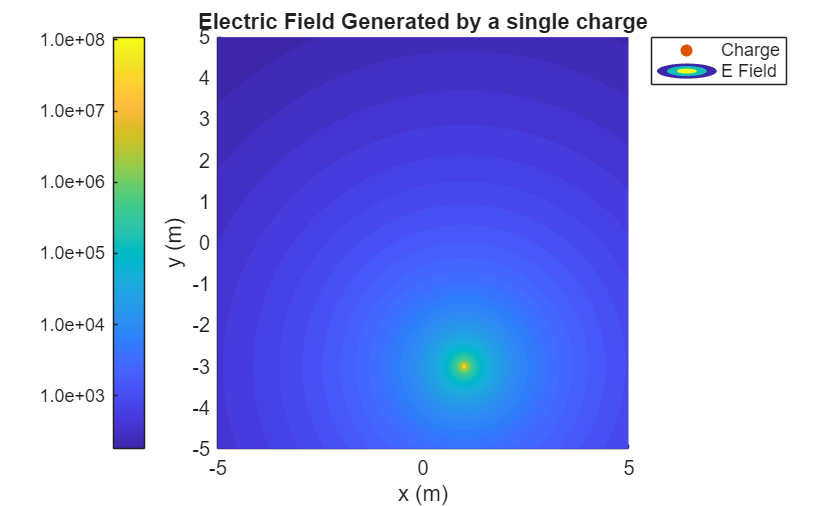

if ~exist("MemSingleChargeField","var")
    MemSingleChargeField = [];
end


MemSingleChargeField = SingleChargeField(MemSingleChargeField,Charge=2,LogScale=true,...
    Method="Filled Contour");

clear MemSingleChargeField

$$\mathrm{In one dimension, the magnitude of the Coulomb force will look like this:}$$

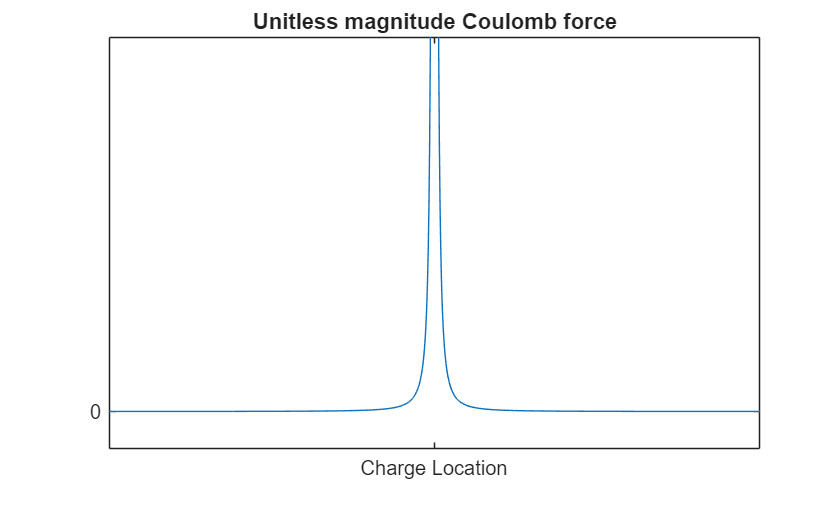

function Mem = SingleChargeField(Mem,opts)

arguments
    Mem
    opts.Charge (1,1) double = 1
    opts.LogScale (1,1) logical = true
    opts.Method (1,1) string = "Contour"
    opts.Reset (1,1) logical = false
end

% Retrieve argument
Method = opts.Method;
Charge = opts.Charge;
LogScale = opts.LogScale;

% Generate a persistent location for the charge
if isempty(Mem)
    [posCharge] = randi([-3,3],1,2);

    xCharge = posCharge(1);
    yCharge = posCharge(2);
    Mem.xCharge = xCharge;
    Mem.yCharge = yCharge;
else
    xCharge = Mem.xCharge;
    yCharge = Mem.yCharge;
end


% Create a grid of points for visualization
switch Method
    case "??"
        warning("Select a valid visualization method.")
        return;
    case "Vector"
        NumPoints = 20;
    case "Contour"
        NumPoints = 400;

$$\mathrm{What is the magnitude of an electric field}3m$$

$$\mathrm{away from a point charge with}q=-3C?$$

    case "Filled Contour"
        NumPoints = 400;
    case "Surface"
        NumPoints = 40;
end

% Compute the field on the grid
[xGrid, yGrid] = meshgrid(linspace(-5,5,NumPoints),linspace(-5,5,NumPoints));
rx = xGrid - xCharge;
ry = yGrid - yCharge;
r = sqrt(rx.^2 + ry.^2);
Charge = Charge*1e-3; % Change charge from microCoulomb to Coulomb
k_e = 8.99e9; % Coulomb's constant in N*m^2/C^2
Ex = k_e * Charge/1000 * rx ./ r.^3;

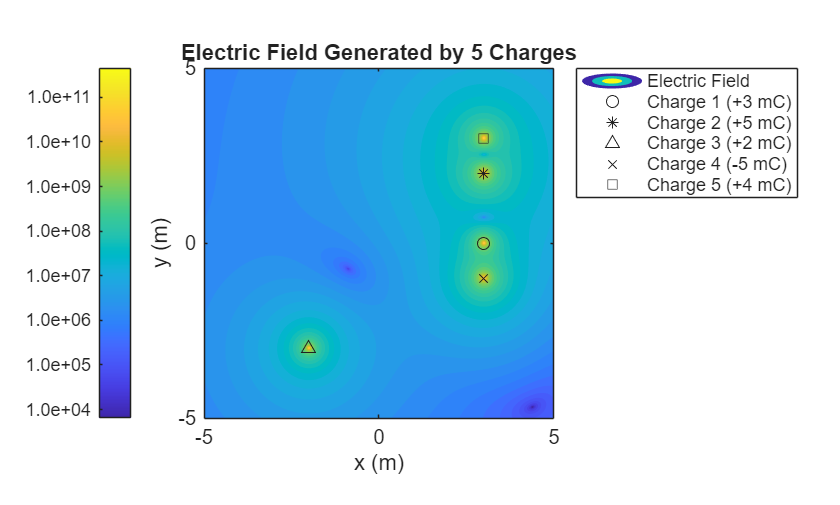

Ey = k_e * Charge/1000 * ry ./ r.^3;
E = sqrt(Ex.^2 + Ey.^2);
dirx = Ex./E;
diry = Ey./E;
if LogScale
    E = log10(E);
end

% Create the figure
figure
if Method == "Surface"
    scatter3(xCharge,yCharge,max(E(:)),"filled",SeriesIndex=2,DisplayName="Charge")
else
    scatter(xCharge,yCharge,"filled",SeriesIndex=2,DisplayName="Charge")
end
hold on
switch Method
    case "Vector"
        quiver(xGrid,yGrid,E.*dirx,E.*diry,AutoScale="on",DisplayName="E Field")
    case "Contour"
        contour(xGrid,yGrid,E,30,DisplayName="E Field")
        cb = colorbar(location="westoutside");
        if LogScale
            Ticks = cb.TickLabels;
            Ticks = convertCharsToStrings(Ticks);
            Ticks = 10.^(double(Ticks));
            cb.TickLabels = num2str(Ticks,'%.1e');
        end
    case "Filled Contour"
        contourf(xGrid,yGrid,E,50,DisplayName="E Field",LineStyle="none")
        cb = colorbar(location="westoutside");
        if LogScale
            Ticks = cb.TickLabels;
            Ticks = convertCharsToStrings(Ticks);

            Ticks = 10.^(double(Ticks));
            cb.TickLabels = num2str(Ticks,'%.1e');
        end
    case "Surface"
        surf(xGrid,yGrid,E,DisplayName="E Field")
        if LogScale
            ax = gca;
            Ticks = ax.ZTickLabels;
            Ticks = convertCharsToStrings(Ticks);
            Ticks = 10.^(double(Ticks));
            ax.ZTickLabels = num2str(Ticks,'%.1e');
        end
end
hold off

title("Electric Field Generated by a single charge")
xlabel('x (m)');
ylabel('y (m)');
axis equal
legend(Location="bestoutside")
xlim([-5 5])
ylim([-5 5])

end


 **Exercise 3.** What happens to the electric field strength as we get close to the point charge?

 
HintExercise3

$$\mathrm{Considering the following point charge distribution:}$$

$$\mathrm{Charge 1:}q=5C\mathrm{located at}0.3m\mathrm{from the origin on the x-axis}$$

$$\mathrm{Charge 2:}q=2C\mathrm{located at}0.3m\mathrm{from the origin on the x-axis}$$

$$\mathrm{What is the magnitude of the electric field at the origin?}$$


function HintExercise3()
displayFormula(['"In one dimension, the magnitude of the Coulomb force will look like this:"'])
figure
x = linspace(0,5,1000);
y = 1./(x-2.5).^2;
plot(x,y)
ylim([-100 1000])
ax = gca;
ax.YTick = 0;
ax.XTick = 2.5;
ax.XTickLabel{1} = "Charge Location";
title("Unitless magnitude Coulomb force")
end

CheckExercise3([]) 

function CheckExercise3(Answer)
if isempty(Answer)
    warning("Please, select an answer")
    return
end

switch Answer
    case 0
        warning("Incorrect. As you approach a point charge, the electric field strength does not decrease to zero.")
    case 1
        warning("Incorrect. The electric field strength changes with distance from a point charge and does not remain constant.")
    case 2
        disp("Correct! As you get closer to a point charge, the electric field strength increases and theoretically approaches infinity.")
end

end

 **Exercise 4.** Use the live control below to generate a problem statement and solve the problem. You can use the edit field below to enter your answer in Newtons, or even type your mathematical formula (use `k_e` in the edit field for the Coulomb constant).

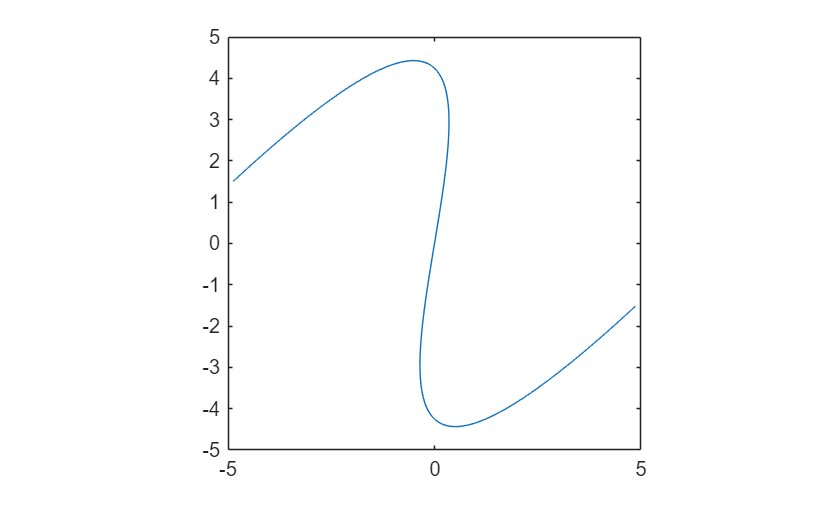

Prob4 = GenerateProblemStatement4; 


function y = GenerateProblemStatement4()
Charge = [-5:-1 1:5];
Charge = Charge(randi(10));
Position = randi([1 5]);
%  fprintf("What is the electric field magnitude felt ( d = %i m)\naway from a point charge (q = %+i C).",Position,Charge)
u = symunit;
displayFormula(['"What is the magnitude of an electric field "' "Position" '" "' "u.m" '" "'; '"away from a point charge with "' "q == Charge" '" "' "u.C" '"?"'])
y.ID = "Ex4";
y.Charge = Charge;
y.Position = Position;
end

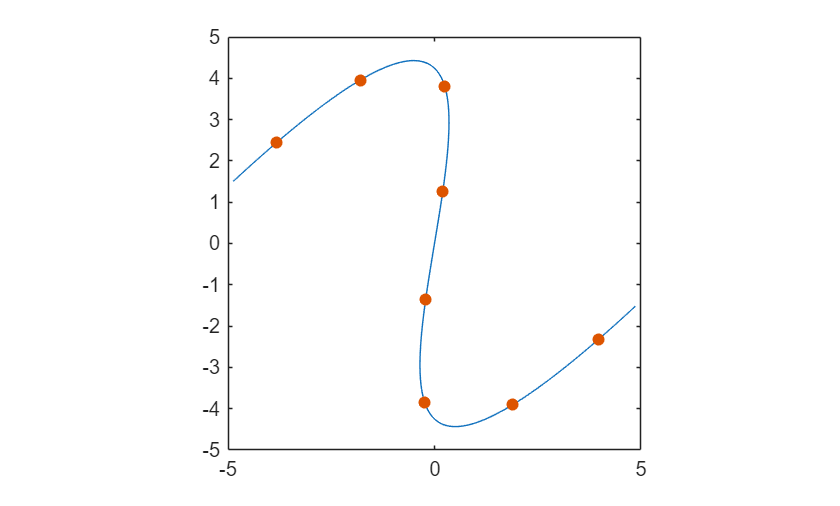

CheckExercise4(Prob4," " )

function CheckExercise4(Prob,Answer)
% Check that it is the right exercise
if ~contains(Prob.ID,"Ex4")

    warning("Click generate problem above to generate a problem statement.")
    return
end

% Check Answer
k_e = "8.99e9";
Answer = replace(Answer,"k_e",k_e);
Answer = double(str2sym(Answer));
RightAnswer = 8.99e9*abs(Prob.Charge)/Prob.Position^2;
if sign(Answer) == -1
    warning("The magnitude of the electric field should be positive.")
end
if isapprox(Answer,abs(RightAnswer),"loose")
    disp("Good job! You computed the magnitude of the force correctly.")
else
    warning("The answer you entered is not correct, make sure that you are using the right formula for the electric field.")
end
end

## What if I have more than one charge?

What about electric fields that are generated by multiple charges? To picture this, think of a cat playing in a box of packing peanuts. When it comes out, static electricity makes the peanuts stick all over its fur each one pulled by the electric charges involved. Similarly, rubbing a balloon on your hair causes the strands to stand up and cling to the balloon. When multiple charges are present, each one influences all the others, creating a complex electric field.

### **Superposition Principle**

The superposition principle states that the total electric field created by multiple charges is the vector sum of the electric fields produced by each charge individually. Mathematically, if $\vec{E}_1$, $\vec{E}_2$, ..., $\vec{E}_n$ are the electric fields due to individual charges, then the total electric field $\mathbf{E}_{\text{total}}$ is given by: 


$$ \vec{E}_{\text{total}} = \vec{E}_1 + \vec{E}_2 + \cdots + \vec{E}_n $$
 

This principle is crucial when dealing with systems of multiple charges, as it allows the calculation of the resultant field by considering each charge separately. 

  **Try.** Visualize the electric field due to multiple charges in space. The charge values (in Coulombs) and their locations in space will be randomized, and you can use the reset button to return the charges and their positions to their initial state.

if ~exist("MemPlotFieldMulti","var")
    MemPlotFieldMulti = [];
end
MemPlotFieldMulti = PlotFieldMulti(MemPlotFieldMulti,NumCharge=5);  

$$\mathrm{The line charge density is}\lambda =0.2\frac{C}{m^{2}}.$$

$$\mathrm{The line is approximately}L=20.5m\mathrm{long.}$$

$$\mathrm{If the line is broken down into}8\mathrm{segments. What is the charge on each segment?}$$

 
clear MemPlotFieldMulti

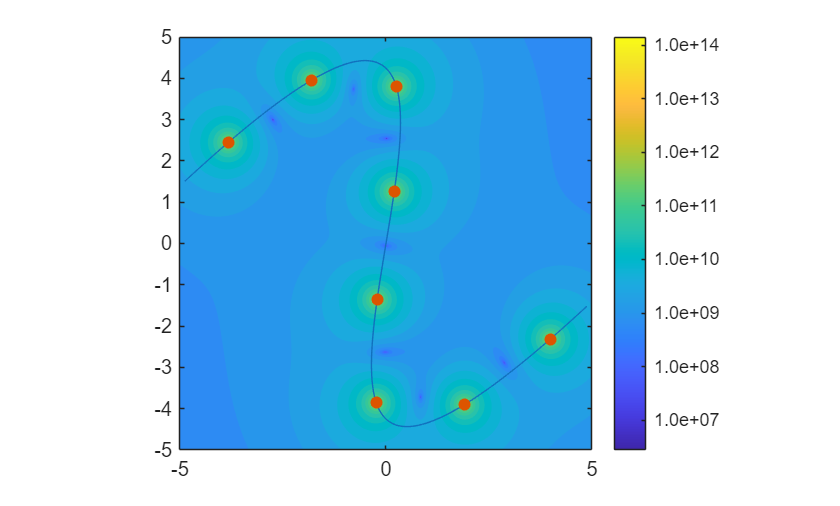

function Mem = PlotFieldMulti(Mem,opts)

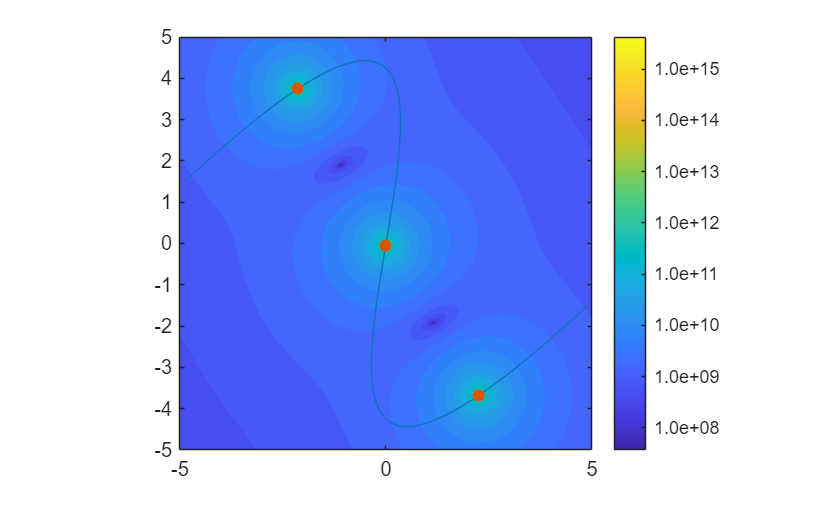

arguments
    Mem
    opts.NumCharge (1,1) double = 4
end

NumCharge = opts.NumCharge;

% Generate memory variable
if isempty(Mem) || opts.NumCharge ~= length(Mem.xCharge)
    [posCharge] = randi([-3,3],NumCharge,2);
    Mem.xCharge = posCharge(:,1);
    Mem.yCharge = posCharge(:,2);
    Charges = [-5:-1 1:5];
    Mem.Charges = Charges(randi(10,NumCharge,1)')*1e-3;
end

% Retrieve memory variable
xCharge = Mem.xCharge;
yCharge = Mem.yCharge;
Charges = Mem.Charges;

% Compute electric field
[xGrid, yGrid] = meshgrid(linspace(-5,5,400),linspace(-5,5,400));
k_e = 8.99e9; % Coulomb's constant in N*m^2/C^2
Ex = zeros(size(xGrid));
Ey = zeros(size(yGrid));
for i = 1:NumCharge
    rx = xGrid - xCharge(i);
    ry = yGrid - yCharge(i);
    r = sqrt(rx.^2 + ry.^2);
    Ex = Ex + k_e * Charges(i) * rx ./ r.^3;
    Ey = Ey + k_e * Charges(i) * ry ./ r.^3;
end
E = sqrt(Ex.^2 + Ey.^2);
E = log10(E);

% Plot results
figure
contourf(xGrid,yGrid,E,40,DisplayName="Electric Field",LineStyle="none")
cb = colorbar(location="westoutside");
Ticks = cb.TickLabels;
Ticks = convertCharsToStrings(Ticks);
Ticks = 10.^(double(Ticks));
cb.TickLabels = num2str(Ticks,'%.1e');
hold on
Marker = replace(linestyleorder("mixedmarkers"),"-","");
for i = 1:NumCharge
    scatter(xCharge(i),yCharge(i),Marker{i},SeriesIndex='none',DisplayName=sprintf("Charge %i (%+i mC)",i,Charges(i)*1000))
end

hold off

title("Electric Field Generated by "+NumCharge+" Charges")
xlabel('x (m)');
ylabel('y (m)');
axis equal
legend(Location="bestoutside")

$$\mathrm{Consider a distribution on a}\mathrm{segment}\mathrm{of}\mathrm{length}3.4m\mathrm{, with a charge density}\lambda =2.0\frac{C}{m}.$$

$$\mathrm{What is the total charge contained in this distribution?}$$

xlim([-5 5])
ylim([-5 5])

end

 **Exercise 5. **Use the live control below to generate a problem statement and solve the problem. You can use the edit field below to enter your answer in V/m, or even type your mathematical formula (you can even use `k_e` in the edit field for the Coulomb constant).

Prob5 = GenerateProblemStatement5; 


function y = GenerateProblemStatement5()
Number = [-5:-1 1:5];
y.ID = "Ex5";
y.Charge1 = Number(randi(10));
y.Charge2 = Number(randi(10));
y.Position1 = Number(randi(10))/10;
y.Position2 = Number(randi(10))/10;
% fprintf("Considering the following point charge distribution:\n")
% fprintf("  - (q = %+i C) located at %+.1f m from the origin on the x-axis\n",y.Charge1,y.Position1)
% fprintf("  - (q = %+i C) located at %+.1f m from the origin on the x-axis\n",y.Charge2,y.Position2)
% fprintf("What is the strength of the electric field at the origin?")

u = symunit;
displayFormula('"Considering the following point charge distribution:"')
displayFormula(['"  Charge 1: "' "q == y.Charge1" '" "' "u.C" '" located at "' sprintf('%.1d',y.Position1) '" "' "u.m" '"from the origin on the x-axis"';...
    '"  Charge 2: "' "q == y.Charge2" '" "' "u.C" '" located at "' sprintf('%.1d',y.Position2) '" "' "u.m" '"from the origin on the x-axis"'])
displayFormula('"What is the magnitude of the electric field at the origin?"')
end

CheckExercise5(Prob5,"" )

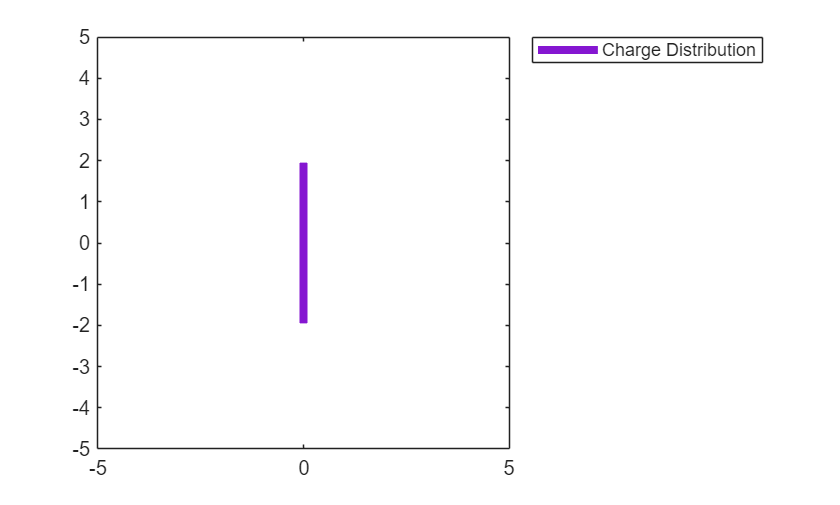


function CheckExercise5(Prob,Answer)
% Check that it is the right exercise
if ~contains(Prob.ID,"Ex5")
    warning("Click generate problem above to generate a problem statement.")
    return
end

% Check Answer
k_e = "8.99e9";
Answer = replace(Answer,"k_e",k_e);
Answer = double(str2sym(Answer));
RightAnswer = 8.99e9*(Prob.Charge1/Prob.Position1^2+Prob.Charge2/Prob.Position2^2);
if sign(Answer) == -1
    warning("The magnitude of the force should be positive."+...
        " You could use the abs() function to retrieve the magnitude of your answer.")
    return
end
if isapprox(Answer,abs(RightAnswer),"loose")
    fprintf("Good job! You computed the magnitude of the force correctly.\n")

    fprintf("  - E ≈ %.2e V/m",RightAnswer)
else
    warning("The ")
end
end

  **Pro-tip.** The superposition principle is one of the principal tools that allows us to compute electrical fields. Instead of trying to solve a large, complex problem, we can break down the problem into contributions from different parts of the system and then add them all up together.

** Application. **To understand how the superposition principle helps solve complex problems, check out the [capacitor script series](matlab:open('.\CapacitorsFundamentals.mlx')). It explains how the principle applies to capacitors.

## Electric Fields Due to Continuous Charge Distributions 

When dealing with electric fields generated by discrete point charges, we can apply Coulomb's law to find the field at a specific point in space by considering each charge's contribution. However, in many real-world scenarios, charges are distributed continuously over a region, such as along a line, over a surface, or throughout a volume. In these cases, the concept of an electric field becomes more complex, and we turn to calculus for help. Using integrals, we can calculate the electric field due to a continuous charge distribution by summing up the infinitesimally small contributions from each tiny charge element across the entire distribution. This approach allows us to account for the cumulative effect of all the charged elements, providing a more comprehensive understanding of the electric field in such situations.

### First Example: Random Line in Space

In this section, we will compute the field generated by a random line with continuous charges in a 2D space step by step.

  **Try. **Click the button below to generate a random line in space

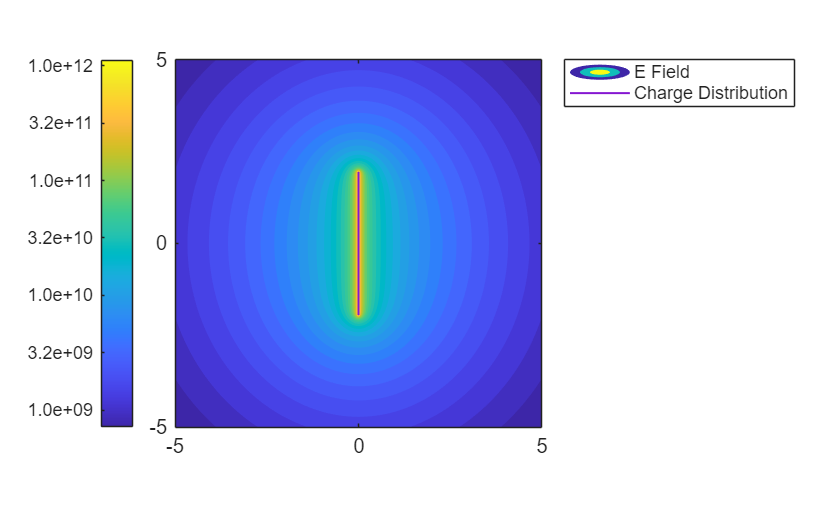

  
Prob6 = GenerateRandomLine;

function Prob = GenerateRandomLine()
figure
Theta = 2*pi*randi(15)/15;

xLine = linspace(-10,10,400);
yLine = 0.1*xLine.^3+0.02*0.02*xLine.^2-2*xLine;
Rot = [cos(Theta), -sin(Theta);sin(Theta) cos(Theta)];
Line = Rot*[xLine;yLine];
xLine = Line(1,:);
yLine = Line(2,:);
id= xLine < 5 & xLine > -5 & yLine < 5 & yLine > -5;
xLine = xLine(id);
yLine = yLine(id);
plot(xLine,yLine)
axis square
xlim([-5 5])
ylim([-5 5])
Prob.xLine = xLine;
Prob.yLine = yLine;
Prob.ID = "GenerateLine";
end


We will approximate the line by discretizing it into multiple segments that will be modeled as discrete points in space. 

  **Try. **Break it down into segments where the points represent the centroid of each segment, discretizing the line.

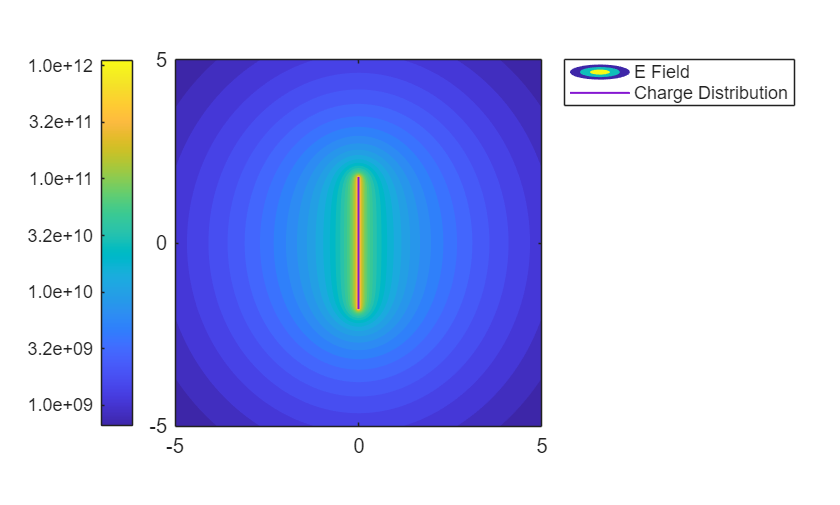

if ~exist("Prob6","var")
    warning("Before to discretize the line, you need to create it with the interaction above.")

else
    Prob6 = BreakDownLine(Prob6,8);   
end

function Prob = BreakDownLine(Prob,NumSeg,NoPlot)
arguments
    Prob (1,1)
    NumSeg (1,1)
    NoPlot = false
end

if ~contains(Prob.ID,"GenerateLine")
    warning("First you should generate a line with the interaction above.")
    return
end

dist = cumsum(sqrt([0 diff(Prob.xLine)].^2 + [0 diff(Prob.yLine)].^2));
distPt = linspace(1/(2*NumSeg)*dist(end),(1-1/(2*NumSeg))*dist(end),NumSeg);
id = floor(interp1(dist,1:length(dist),distPt));
Prob.xPt = Prob.xLine(id);
Prob.yPt = Prob.yLine(id);
Prob.Length = dist(end);
Prob.NumSegment = NumSeg;
if ~NoPlot
    figure
    plot(Prob.xLine,Prob.yLine)
    hold on
    scatter(Prob.xPt,Prob.yPt,'filled')
    axis square
    xlim([-5 5])
    ylim([-5 5])
end
if ~contains(Prob.ID,"_BreakDown")
    Prob.ID = Prob.ID+"_BreakDown";
end
end

Now that we have simplified the geometry into a set of points, we need to assign an appropriate charge to each of those points.

 **Exercise 6. **Use the live control below to generate and solve a problem.

 
if ~exist("Prob6","var")
    warning("Before to attempt this exercise, please run the interaction above to create and discretize the line.")
else
    Prob6 = GenerateProblemStatement6(Prob6);
end

function Prob = GenerateProblemStatement6(Prob)
if ~contains(Prob.ID,"BreakDown")
    warning("First you should break the line into multiple segment using the interaction above.")
    if contains(Prob.ID,"GenerateLine")
        Prob = BreakDownLine(Prob,8);
    end
    return
end
if ~isfield(Prob,"Lambda")
    Lambda = [-0.5:0.1:-0.1 0.1:0.1:0.5];
    Prob.Lambda = Lambda(randi(length(Lambda)));
end

ApproxLambda = round(vpa(Prob.Lambda,6),1); %#ok<NASGU>
ApproxLength = round(vpa(Prob.Length,6),1); %#ok<NASGU>
u = symunit; %#ok<NASGU>

displayFormula(['" The line charge density is "' "lambda == ApproxLambda" '" "' "u.C/u.m^2" '"."'; ...
    '" The line is approximately "' "L == ApproxLength" '" "' "u.m" '" long."';...
    '"If the line is broken down into "' "Prob.NumSegment" '" "' "" '"segments. What is the charge on each segment?"'])
if ~contains(Prob.ID,"_Ex6")
    Prob.ID = Prob.ID +"_Ex6";
end
end

Prob6 = CheckExercise6(Prob6," " );

function Prob = CheckExercise6(Prob,Answer)
if ~contains(Prob.ID,"Ex6")
    warning("First you should generate a problem statement above.")
    return
end

RightAnswer = sprintf("%.1f * %.1f / %i",Prob.Lambda,Prob.Length,Prob.NumSegment);
RightAnswer = double(str2sym(RightAnswer));
Answer = double(str2sym(Answer));

if isapprox(Answer,RightAnswer,"veryloose")
    disp("Good job! You computed the equivalent individual charges correctly.")
    Prob.Solved = true;
else
    warning("Try again! The individual charge should be a function of λ, L and the number of segments.")
end

end

  **Try. **Use superposition to compute the field.

PlotLineFied(Prob6); 

function PlotLineFied(Prob)
if ~contains(Prob.ID,"Ex6")
    warning("First you should solve the exercise above.")
    return
end

% Define parameters for the charges and distance
k_e = 8.99e9; % Coulomb's constant in N*m^2/C^2

% Create a grid of points for visualization
[xGrid, yGrid] = meshgrid(linspace(-5,5,400),linspace(-5,5,400));
% Initialize electric field components
Ex = zeros(size(xGrid));
Ey = zeros(size(yGrid));

% Compute electric field components due to charge Q1
Charge = Prob.Lambda*Prob.Length/Prob.NumSegment;
for i = 1:Prob.NumSegment
    dx = xGrid - Prob.xPt(i);
    dy = yGrid - Prob.yPt(i);
    r = sqrt(dx.^2 + dy.^2);
    Ex = Ex + k_e * Charge * dx ./ r.^3;
    Ey = Ey + k_e * Charge * dy ./ r.^3;
end

E = sqrt(Ex.^2 + Ey.^2);
E = log10(E);

figure
contourf(xGrid,yGrid,E,30,DisplayName="Field",LineStyle="none")
cb = colorbar;
Ticks = cb.TickLabels;
Ticks = convertCharsToStrings(Ticks);
Ticks = 10.^(double(Ticks));
cb.TickLabels = num2str(Ticks,'%.1e');
hold on
plot(Prob.xLine,Prob.yLine)
scatter(Prob.xPt,Prob.yPt,'filled')
hold off
axis square
xlim([-5 5])
ylim([-5 5])

end

  **Try. **Use the live control below to repeat the step above with more points to more finely discretize the line.

Prob6 = BreakDownLine(Prob6,3,true);
PlotLineFied(Prob6);

 **Reflect.** How many segments would you need to accurately represent an electric field?

In the previous problem, we considered a 1D distribution of charge. Although the problem was in a 2D (x-y) plane, the distribution was along a line (1D). 

 **Exercise 7.** Use the live control below to generate a problem statement and solve the problem. You can use the edit field below to enter your answer in Newton, or even type your mathematical formula (you can even use `k_e` in the edit field for the Coulomb constant).

 
Prob7 = GenerateProblemStatement7;

function Prob = GenerateProblemStatement7()
% Generate problem statement
Prob.ID = "Ex7";
Prob.Dimension = randi(3); % Problem dimension
u = symunit;
switch Prob.Dimension
    case 1
        Prob.Letter = sym("lambda");
        Prob.Unit = u.C/u.m;
        Prob.Shape = "segment";
        Prob.DimName = "length";
    case 2
        Prob.Letter = sym("sigma");
        Prob.Unit = u.C/u.m^2;
        switch randi(2)
            case 1
                Prob.Shape = "square";
                Prob.DimName = "length";
            case 2
                Prob.Shape = "disk";
                Prob.DimName = "radius";
        end
    case 3
        Prob.Letter = sym("rho");
        Prob.Unit = u.C/u.m^3;
        switch randi(2)
            case 1
                Prob.Shape = "cube";
                Prob.DimName = "length";
            case 2
                Prob.Shape = "sphere";
                Prob.DimName = "radius";
        end
end
Prob.Length = 2:0.2:4;
Prob.Length = Prob.Length(randi(length(Prob.Length)));
Prob.Charge = 2:0.2:4;
Prob.Charge = Prob.Charge(randi(length(Prob.Charge)));

% Display problem statement
ApproxCharge = round(vpa(Prob.Charge,6),1);
ApproxLength = round(vpa(Prob.Length,6),1);
switch randi(2)
    case 1 % Compute total charge
        Prob.Case = "Total";
        displayFormula(['"Consider a distribution on a "' 'Prob.Shape' '" of "' 'Prob.DimName' '" "' "ApproxLength" '" "' "u.m" '", with a charge density "' "Prob.Letter == ApproxCharge" '" "' "Prob.Unit" '"."'])
        displayFormula('"What is the total charge contained in this distribution?"')
    case 2 % Compute charge density
        Prob.Case = "Density";
        displayFormula(['"Consider a distribution on a "' 'Prob.Shape' '" of "' 'Prob.DimName'  " "' "ApproxLength" '" "' "u.m" '", with a total charge of "' "ApproxCharge" '" "' "u.C" '"."'])
        displayFormula('"What is the charge density of this distribution?"')
end
end


CheckExercise7(Prob7,"" )

function CheckExercise7(Prob,MyAnswer)

if ~contains(Prob.ID,"Ex7")
    warning("First you should generate a problem statement above.")
    return
end

if MyAnswer == ""
    warning("Please complete your answer.")
    return
else
    MyAnswer = double(str2sym(MyAnswer)); % Convert the user's answer to a numeric value
end

switch Prob.DimName
    case "length"
        switch Prob.Dimension
            case 1
                Surface = Prob.Length;
            case 2
                Surface = Prob.Length^2;
            case 3
                Surface = Prob.Length^3;
        end
    case "radius"
        switch Prob.Dimension
            case 2
                Surface = pi*Prob.Length^2;
            case 3
                Surface = 4/3*pi*Prob.Length^3;
        end
end

switch Prob.Case
    case "Total"
        Answer = Prob.Charge * Surface;
        CommonWrong = Prob.Charge / Surface;
        if isapprox(Answer,MyAnswer,"loose")
            disp("Good job! You computed the total charge correctly. Generate and new problem statement and try again!")
        else
            if isapprox(CommonWrong,MyAnswer,"loose")
                warning("The formula you used to compute the total charge is wrong."+newline+...
                    "Hint: your computation would have been correct for charge density")
            else
                warning("Your computation is wrong, try again!")
            end
        end
    case "Density"
        Answer = Prob.Charge / Surface;
        CommonWrong = Prob.Charge * Surface;
        if isapprox(Answer,MyAnswer,"loose")
            disp("Good job! You computed the charge density correctly. Generate and new problem statement and try again!")
        else
            if isapprox(CommonWrong,MyAnswer,"loose")
                warning("The formula you used to compute the charge density is wrong."+newline+...
                    "Hint: your computation would have been correct for total charge")
            else
                warning("Your computation is wrong, try again!")
            end
        end
end
end

This approach of breaking down the problem into smaller pieces can be very useful, but sometimes the problem can also be solved using tools from calculus!

 **Exercise 8.** What calculus tool can you think of to calculate some of these without going to an infinite number of segments?

CheckExercise8("??")

function CheckExercise8(MyAnswer)
switch MyAnswer
    case "??"
        warning("Please select a valid answer.")
    case "Derivative"
        warning("Useful for finding the rate of change, but not for directly computing electric fields from charge distributions.")
    case "Integral"
        disp("Correct! Integrals are used to sum contributions from charge elements to find the total electric field.")
    case "Series"
        warning("Series help approximate functions but aren't typically used for calculating electric fields from charge distributions.")
    case "Fourier Analysis"
        warning("Useful for frequency decomposition, but not the primary method for computing electric fields from charge distributions.")
end
end

### Second Example: A Finite Charged Line

In this example, we solve for the electric field using calculus and use MATLAB to represent the field.

  **Try. **We are considering a finite length vertical charged line with a uniform charge density ($\lambda$). Use the slider below to define the length of the line.

ProbEnd = DrawFiniteLine(3.9); 


function Prob = DrawFiniteLine(L,EnablePlot)
arguments
    L (1,1)
    EnablePlot (1,1) logical = true;
end

Prob.ID = "DrawLine";
Prob.Length = L;
Prob.Lambda = 1.0;

if EnablePlot
    figure
    y = linspace(-L/2,L/2,2);
    x = 0.*y;
    plot(x,y,LineWidth=4,SeriesIndex=4,DisplayName="Charge Distribution")
    legend(Location="bestoutside")
    axis square
    xlim([-5 5])
    ylim([-5 5])
end

end

Consider a line of charge extending from $y=-\frac{L}{2}$ to $y=\frac{L}{2}$ along the $y$-axis. Let the linear charge density be $\lambda$ (charge per unit length). We aim to find the electric field at any point ($P$) located at a distance $x$ from the $y$-axis on the $x$-axis.

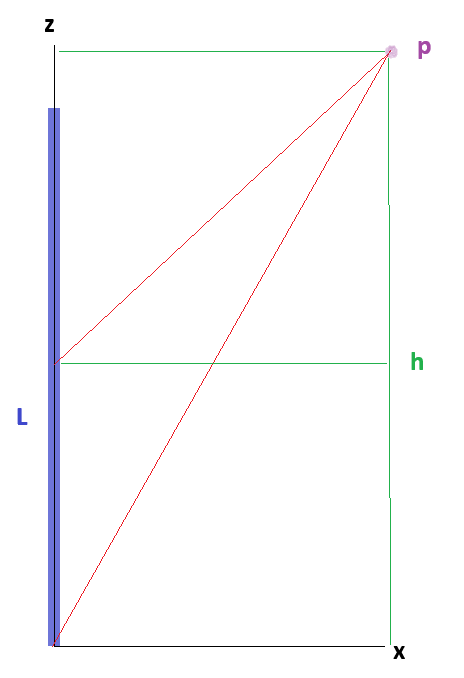

Choose a small element charge $dq$ located at a distance $h$ from the center of the line. The differential charge is given by:


$$dq = \lambda dh$$


The electric field due to the differential charge $dq$ at the point $P$ can be expressed using Coulomb's Law. The distance from $dq$ to $P$ is:


$$r = \sqrt{x^2+(y-h)^2}$$


The differential electric field $d\vec{E}$ due to $dq$ is:


$$d\vec{E}=k_e\frac{dq}{r^2}\hat{r}$$


The electric field has both $x$ and $y$ components:


$$d{E_x}=k_e\frac{dq}{r^3}x = k_e \frac{\lambda dh\,x}{(x^2+(y-h)^2)^{3/2}}$$



$$d{E_y}=k_e\frac{dq}{r^3}(y-h) = k_e \frac{\lambda (y-h) dh}{(x^2+(y-h)^2)^{3/2}}$$


Integrate over the length of the line:


$$E_x= \frac{k_e \lambda}{2x} \left( \frac{L+2y}{\sqrt{x^2 + (L/2+y)^2}} + \frac{L-2y}{\sqrt{x^2 + (L/2-y)^2}} \right)$$



$$E_x= k_e\lambda \left( \frac{1}{\sqrt{x^2+(y-L/2)^2}} - \frac{1}{\sqrt{x^2+(y+L/2)^2}} \right)$$


  **Try. **Visualize the answer. 

 
if ~exist("ProbEnd","var")
    warning("Solving the problem with line of length 1 m.")
    ProbEnd = DrawFiniteLine(1,false)
end
PlotFieldFiniteLine(ProbEnd)
function PlotFieldFiniteLine(Prob)

k_e = 8.999e9;
lambda = Prob.Lambda;
L = Prob.Length;
Ex = @(x,y) k_e*lambda * 1./(2.*x) .* ( (L+2*y)./sqrt(x.^2 + (L/2+y).^2) + (L-2*y)./sqrt(x.^2 + (L/2-y).^2) );
Ey = @(x,y) k_e*lambda * ( 1./sqrt(x.^2 + (y-L/2).^2) - 1./sqrt(x.^2 + (y+L/2).^2) );

[xGrid,yGrid] = meshgrid(linspace(-5,5,400),linspace(-5,5,400));
E = sqrt(Ex(xGrid,yGrid).^2 + Ey(xGrid,yGrid).^2);
figure
contourf(xGrid,yGrid,log10(E),30,LineStyle="none",DisplayName="E Field")
hold on
y = linspace(-L/2,L/2,2);
x = 0.*y;
plot(x,y,LineWidth=1,SeriesIndex=4,DisplayName="Charge Distribution")
hold off

cb = colorbar(location="westoutside");
Ticks = cb.TickLabels;
Ticks = convertCharsToStrings(Ticks);
Ticks = 10.^(double(Ticks));
cb.TickLabels = num2str(Ticks,'%.1e');

legend (location="bestoutside")
axis square
xlim([-5 5])
ylim([-5 5])
end

 **Note. **What happens when the line becomes very long? What happens when the line becomes very short? (How does it compare to a discrete point charge?)

ProbEnd = DrawFiniteLine(3.601,false);
PlotFieldFiniteLine(ProbEnd);

## Further Exploration

In this script, you had many interactions creating visualizations of electric fields. If you would like to learn how to visualize an electric field in MATLAB, you should complete VisualizeField.mlx.

## Conclusion 

In this lesson, we examined the relationship between electric charges and electric fields. We covered the superposition principle and learned how to compute electric fields from point charges and continuous charge distributions. Visualizing the Coulomb force and electric fields helped us gain a clearer and more intuitive understanding of these concepts. Grasping these ideas is key to analyzing a wide range of physical phenomena in electromagnetism, and it sets a solid foundation for further exploration in the field.

[⇦ Main Menu](matlab:open('MainMenu.mlx'))